location = uigetdir()

location = 'C:\Users\Asad PC\Documents\MATLAB\Computer Vision for Engineering and Science\Data\MathWorks Images\Roadside Ground Cover'

dsSnow = imageDatastore(location, "IncludeSubfolders",true, "LabelSource","foldernames")

dsSnow =   ImageDatastore with properties:

                       Files: {
                              ' ...\Data\MathWorks Images\Roadside Ground Cover\No Snow\RoadsideA_1.jpg';
                              ' ...\Data\MathWorks Images\Roadside Ground Cover\No Snow\RoadsideA_10.jpg';
                              ' ...\Data\MathWorks Images\Roadside Ground Cover\No Snow\RoadsideA_100.jpg'
                               ... and 197 more
                              }
                     Folders: {
                              ' ...\Data\MathWorks Images\Roadside Ground Cover'
                              }
                      Labels: [No Snow; No Snow; No Snow ... and 197 more categorical]
    AlternateFileSystemRoots: {}
                    ReadSize: 1
      SupportedOutputFormats: ["png"    "jpg"    "jpeg"    "tif"    "tiff"]
         DefaultOutputFormat: "png"
                     

[dsTrain, dsTest] = splitEachLabel(dsSnow, 0.85, "randomized");
sum(dsTrain.Labels == "Snow")

ans = 85

img = imread("Data/MathWorks Images/Roadside Ground Cover/No Snow/RoadsideA_1.jpg");
imgHSV = rgb2hsv(img);
imgSaturation = imgHSV(:, :, 2);

imgMeanSaturation = mean(imgSaturation(:))

imgMeanSaturation = 0.3806

imgSTDSaturation = std(imgSaturation(:))

imgSTDSaturation = 0.2302

snowTable = extractSnowFeatures(dsTrain);

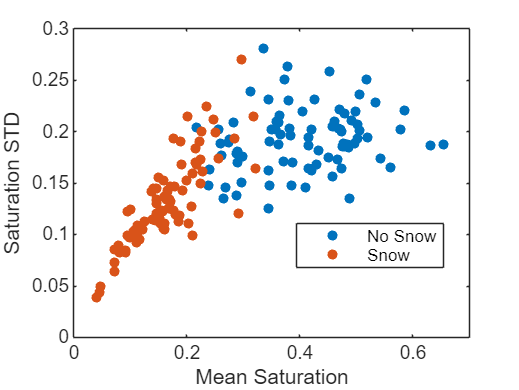

gscatter(snowTable.saturationAvg, snowTable.saturationSTD, snowTable.label)
xlabel("Mean Saturation")
ylabel("Saturation STD")

snowTestTable = extractSnowFeatures(dsTest);